# Initialization

## Path

clear all; close all; 

% set current file path 
filePath = matlab.desktop.editor.getActiveFilename;
pathDivided=strsplit(filePath,'\');
newPath=erase(filePath,pathDivided(end));
dataPath=strcat(newPath,'dataset');
% set folder with net syntax
imds = imageDatastore(strcat(newPath,'dataset\FRAME_TRAIN')); % link for training frame
pxds = pixelLabelDatastore(strcat(newPath,'dataset\GT_TRAIN'),["N","B"],[0 1]); % link for GT images
f_test=dir(strcat(dataPath,'/FRAME_TEST_SEG/*.tiff'));
gt_train=dir(strcat(dataPath,'/GT_TEST/*.tiff'));

addpath(strcat(newPath,'functions')); %set path for functions

## ResNet50

net=resnet50;
numClasses=2; % foreground and background
imageSize=net.Layers(1).InputSize; %read size directly from net
augmenter = imageDataAugmenter('RandRotation',[0 360],'RandXReflection',true,'RandXTranslation',[-20 20],'RandYTranslation',[-20 20]);
pximds = pixelLabelImageDatastore(imds,pxds,'DataAugmentation',augmenter,'OutputSize',imageSize,'ColorPreprocessing','gray2rgb');
lgraph = deeplabv3plusLayers(imageSize, numClasses, "resnet50"); 
% balance predominance of 0
tbl = countEachLabel(pximds);
totalNumberOfPixels = sum(tbl.PixelCount);
frequency = tbl.PixelCount / totalNumberOfPixels;
classWeights = 1./frequency;
pxLayer = pixelClassificationLayer('Name','labels','Classes',tbl.Name,'ClassWeights',classWeights);
lgraph = replaceLayer(lgraph,"classification",pxLayer);

Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:03 |       51.11% |       0.7851 |          0.0100 |
|       8 |          50 |       00:01:06 |       91.27% |       0.2242 |          0.0100 |
|      15 |         100 |       00:02:13 |       93.71% |       0.1168 |          0.0100 |
|      22 |         150 |       00:03:21 |       93.47% |       0.1147 |          0.0100 |
|      29 |         200 |       00:04:32 |       93.48% |       0.0924 |          0.0100 |
|      36 |         250 |       00:05:45 |       96.25% |       0.0689 |          0.0100 |
|      40 |         280 |  

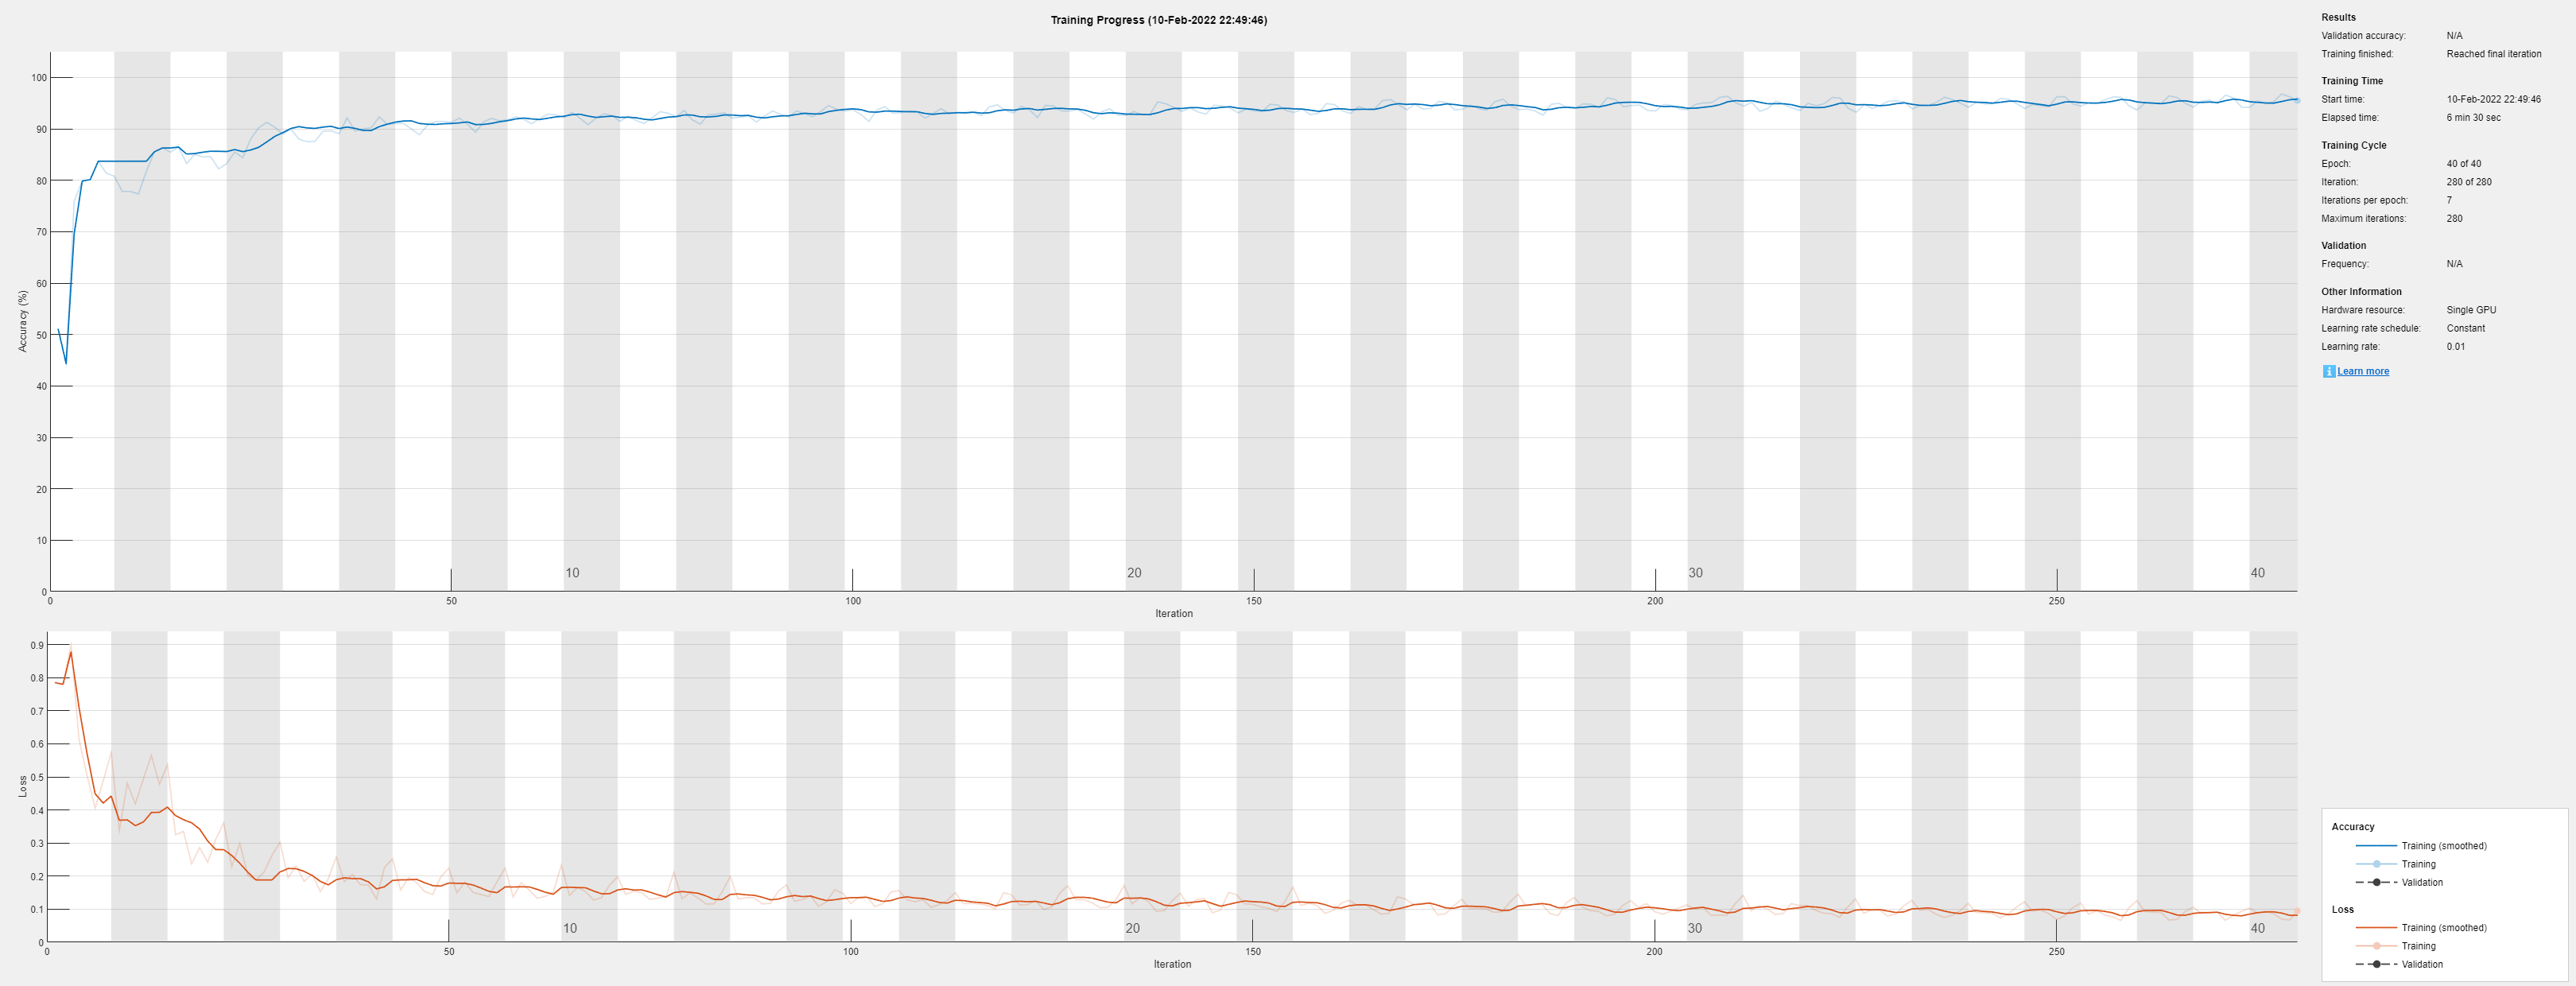

net_resnet50 =   DAGNetwork with properties:

         Layers: [206×1 nnet.cnn.layer.Layer]
    Connections: [227×2 table]
     InputNames: {'input_1'}
    OutputNames: {'labels'}


info_resnet50 = struct with fields:
        TrainingLoss: [1×280 double]
    TrainingAccuracy: [1×280 double]
       BaseLearnRate: [1×280 double]


FM_test_resnet50 =     0.8664    0.6626    0.6955    0.7723    0.7331    0.7277    0.6530    0.6818    0.8116    0.5398    0.8364    0.8246    0.5227    0.7650    0.8189    0.7108    0.8464    0.7356    0.6162    0.7114    0.8213    0.7463    0.6867    0.7411    0.7535    0.8489    0.8344    0.8655    0.5813    0.8923    0.9068    0.8189    0.8180    0.7005


compTime_resnet50 = 14.5958

[net_resnet50, info_resnet50, FM_test_resnet50,compTime_resnet50]=trainAndTest(pximds,lgraph,dataPath,f_test,gt_train);

disp('Test for ResNet50')

Test for ResNet50


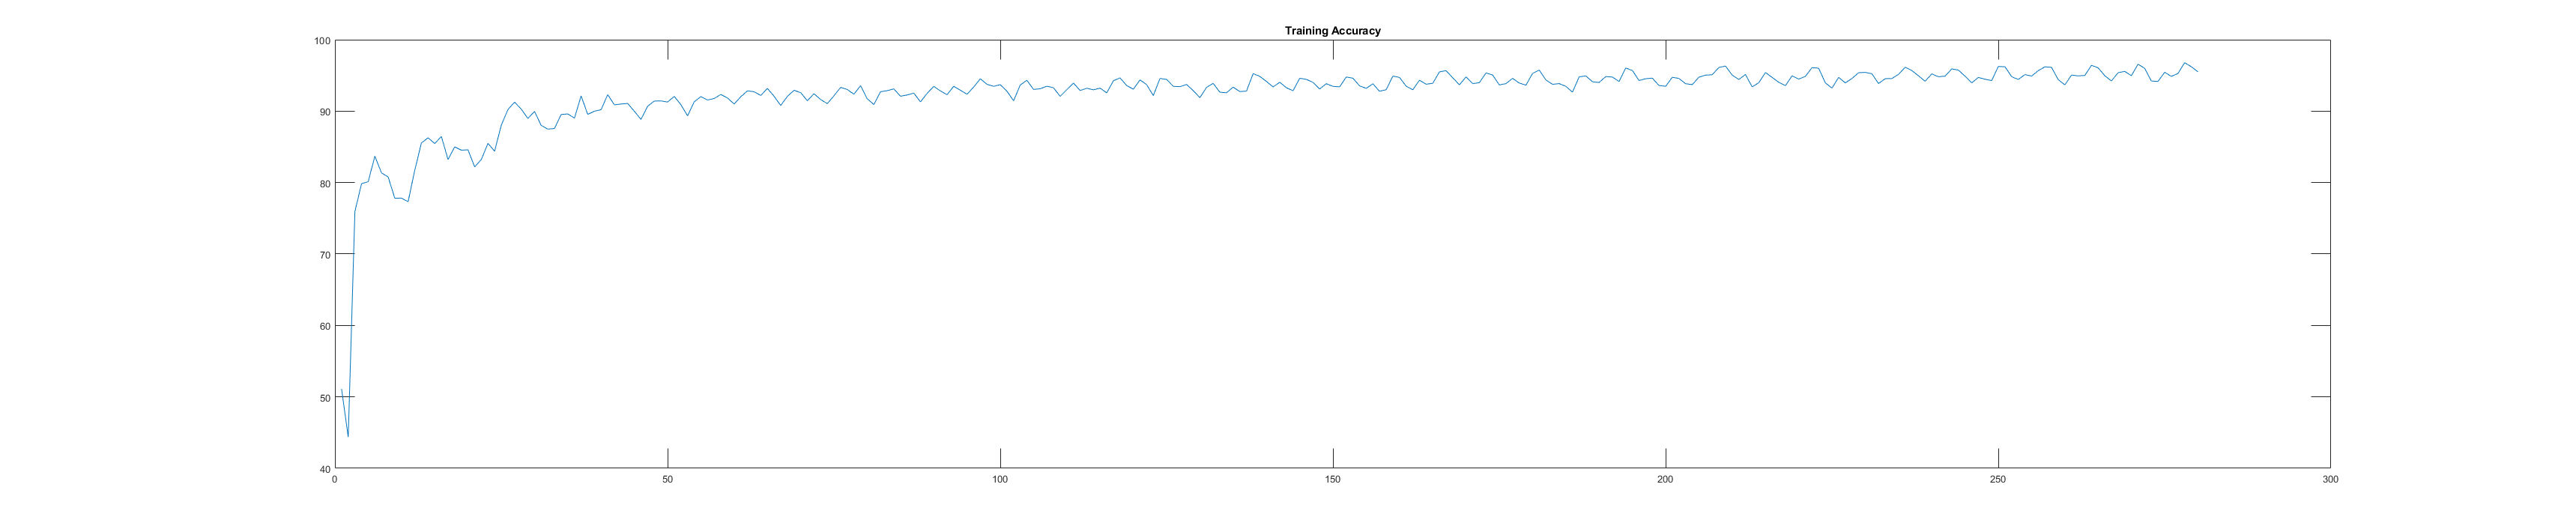

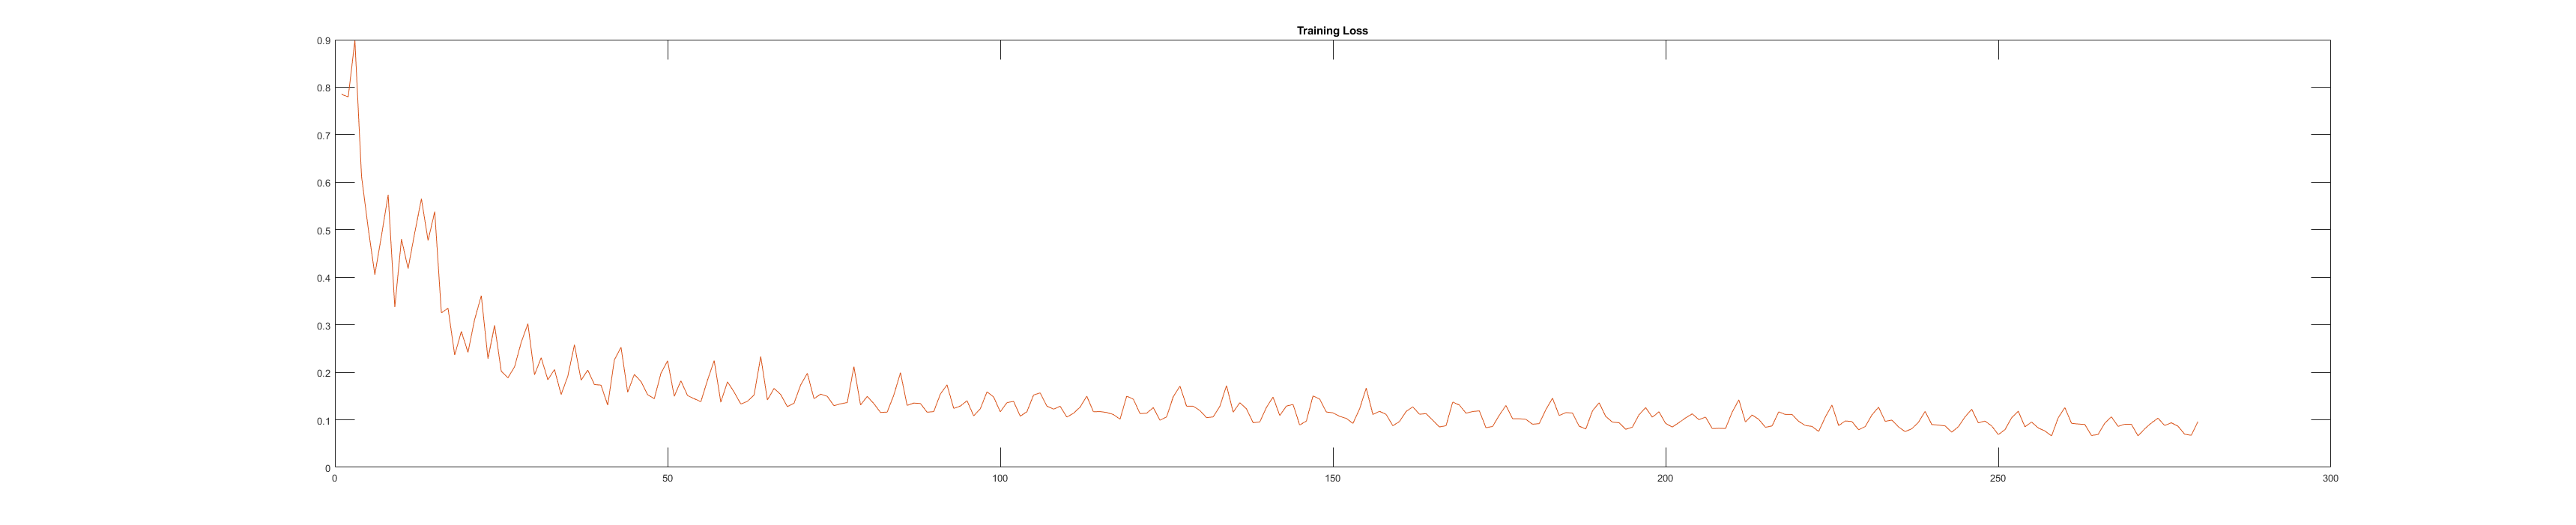

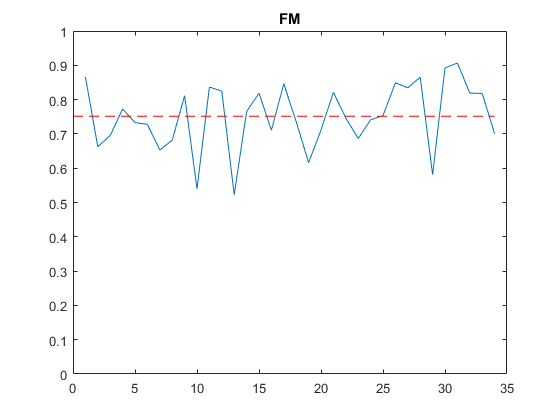

FM mean: 0.75139
FM max: 0.90675
FM min: 0.52266
FM std: 0.097241
accuracy: 95.5109
loss: 0.096085


[accuracy_resnet50,loss_resnet50,FM_mean_resnet50]=figureAccAndLoss(info_resnet50,FM_test_resnet50);

## ResNet18

% resnet50 resnet18 mobilenetv2 xception inceptionresnetv2

[pximds,lgraph]=prepareMyNet(resnet18,'resnet18',imds,pxds);

resnet18 ready


[net_resnet18, info_resnet18, FM_test_resnet18,compTime_resnet18]=trainAndTest(pximds,lgraph,dataPath,f_test,gt_train);

Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:03 |       44.56% |       0.8088 |          0.0100 |


Not enough input arguments.

Error in figureAccAndLoss (line 12)
plot(FM_test);

[accuracy_resnet18,loss_resnet18,FM_mean_resnet18]=figureAccAndLoss(info_resnet18,FM_test_resnet18)